# Bulk RECON1 Gene KO Analysis

**Author:** Scott Campit

## Summary

This script computes bulk differentially acitve reactions between epithelial and mesenchymal cells in the RECON1 metabolic model.

clear all;

## 1. Load data

We'll load the RECON1 data obtained from three independent EMT studies induced with TGF-B:

- GSE17518 (Thannickal transcriptomics)

- GSE17708 (Keshamouni transcriptomics)

- Garcia proteomics data

**Note** that the primary assumption is that mesenchymal cells are more likely to be found in later time points than earlier ones.

Let's first load RECON1 reaction IDs.

load D:/Data/Reconstructions/RECON1/recon1.mat
[gene_id, idx] = unique(string(recon1.geneEntrezID));

### A. GSE17518

Note that this experiment compared hour 72 versus hour 0.

#### i. Load data

First we'll load all of the data as a single vector. 

GSE17518_labels = "72/0hrs";
datapath = dir(fullfile("D:/Analysis/EMT/gse17518/recon1/", "*.mat"));
load(strcat(datapath.folder, '\', datapath.name));
GSE17518_grate = cobra_cell.geneko;

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

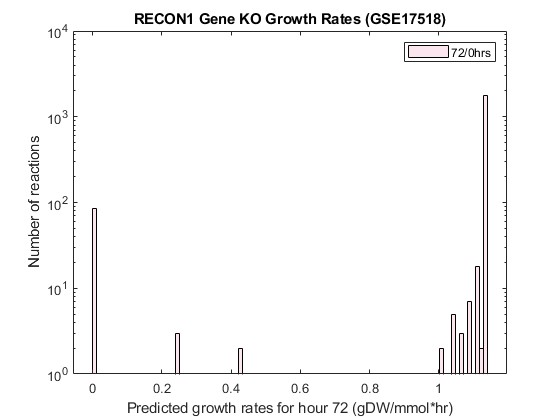


tmp_flux =

  0×1905 empty double matrix



Unrecognized function or variable 'rxn_ids'.

figure;
h1 = histogram(GSE17518_grate, 100);
set(h1, 'facecolor', "#f9d5e5");
legend(GSE17518_labels);
set(gca, 'YScale', 'log')
title("RECON1 Gene KO Growth Rates (GSE17518)");
xlabel("Predicted growth rates for hour 72 (gDW/mmol*hr)");
ylabel("Number of reactions");

### B. GSE17708

#### i. Load data

First we'll load all of the data as a single dataframe.

GSE17708_labels = string();
datapath = dir(fullfile("D:/Analysis/EMT/gse17708/recon1/", "*.mat"));
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    GSE17708_grate(:, i) = cobra_cell.geneko;
    GSE17708_labels(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

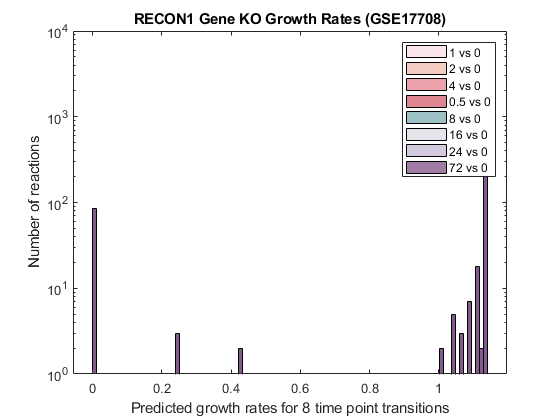

figure;
h1 = histogram(GSE17708_grate(:, 1), 100);
hold on;
h2 = histogram(GSE17708_grate(:, 2), 100);
hold on;
h3 = histogram(GSE17708_grate(:, 3), 100);
hold on;
h4 = histogram(GSE17708_grate(:, 4), 100);
hold on;
h5 = histogram(GSE17708_grate(:, 5), 100);
hold on;
h6 = histogram(GSE17708_grate(:, 6), 100);
hold on;
h7 = histogram(GSE17708_grate(:, 7), 100);
hold on;
h8 = histogram(GSE17708_grate(:, 8), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");
set(h5, 'facecolor', "#5b9aa0");
set(h6, 'facecolor', "#d6d4e0");
set(h7, 'facecolor', "#b8a9c9");
set(h8, 'facecolor', "#622569");

legend(GSE17708_labels);
set(gca, 'YScale', 'log')
title("RECON1 Gene KO Growth Rates (GSE17708)");
xlabel("Predicted growth rates for 8 time point transitions");
ylabel("Number of reactions");

### C. Garcia proteomics

#### i. Load data

First we'll load all of the data as a single dataframe.

datapath = dir(fullfile("D:/Analysis/EMT/garcia/recon1/", "*.mat"));
Garcia_labels = string();
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    Garcia_grate(:, i) = cobra_cell.geneko;
    Garcia_labels(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

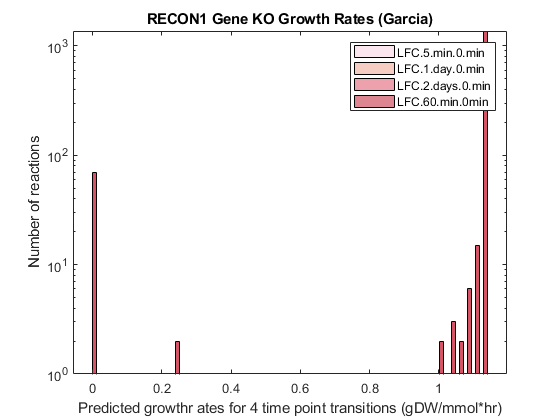

figure;
h1 = histogram(Garcia_grate(:, 1), 100);
hold on;
h2 = histogram(Garcia_grate(:, 2), 100);
hold on;
h3 = histogram(Garcia_grate(:, 3), 100);
hold on;
h4 = histogram(Garcia_grate(:, 4), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");

legend(Garcia_labels);
set(gca, 'YScale', 'log')
title("RECON1 Gene KO Growth Rates (Garcia)");
xlabel("Predicted growthr ates for 4 time point transitions (gDW/mmol*hr)");
ylabel("Number of reactions");

### D. Major takeaways from all of the datasets

It appears that specific transport and exchange reactions that have fluxes greater than 5 or less than negative 5 are always skewing the data distribution. These need to be filtered out from downstream analyses.

## 2. Compute differentially sensitive reactions

### A. Concatenate the data

We'll construct 1 large dataframe of all reactions. We'll also ensure the absolute value for the reactions is taken to remove reaction directionality - just consider magnitude of activity.

data = [GSE17518_grate(idx)', GSE17708_grate(idx, :), Garcia_grate];

### B. Visualize the flux data distribution across all studies

To get a sense of the entire dataset, let's visualize the entire flux distribution.

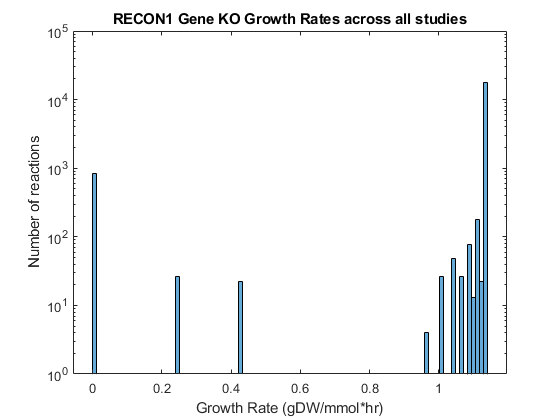

figure;
histogram(data, 100);
set(gca, 'YScale', 'log')
title("RECON1 Gene KO Growth Rates across all studies");
xlabel("Growth Rate (gDW/mmol*hr)");
ylabel("Number of reactions");

### C. Identify up- and downregulated metabolic reactions

#### i. Compute mean flux across all experiments for each reaction

We'll now take the average flux value across all experiments for each reaction

mu = median(data, 'all');
%mu = mean(data, 2);

#### ii. Compute standard deviation across all experiments for each reaction

We'll also take the standard deviation across all experiments for each reaction

sigma = (1.4826*mad(data, [], 'all'));
%sigma = std(data, [], 2);

#### iii. Median normalize the data

Now let's take the Z-score for all reactions using the mean and standard deviation computed above.

data_norm = data ./ mu;
data_norm(isinf(data_norm)) = max(data_norm(isfinite(data_norm)));
data_norm(isnan(data_norm)) = 0;

#### iv. Compute p-values for metabolic fluxes

Transform the Z-scores into p-values.

%mu2 = median(data, 'all');
%sigma2 = (1.4826*mad(data, [], 'all'));
%pvalue = normpdf(data_norm);
%histogram(pvalue, 100)

#### v. Visualize the data distribution

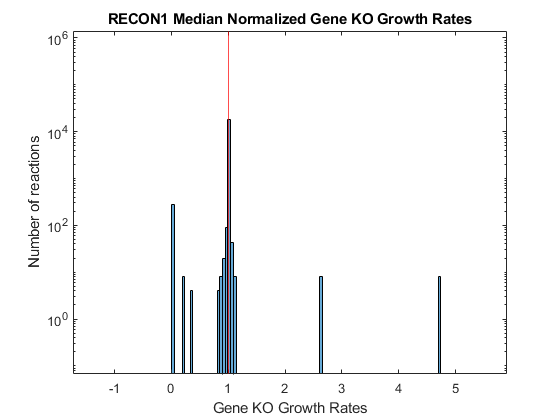

figure;
histogram(data_norm, 100);
set(gca, 'YScale', 'log')
title("RECON1 Median Normalized Gene KO Growth Rates");
xlabel("Gene KO Growth Rates");
ylabel("Number of reactions");
xline(1, 'r')

#### vi. Get final reaction table

First load the sample ids.

sample_ids = [GSE17518_labels, GSE17708_labels, Garcia_labels];

Next, get the index for reactions to remove. Keep reactions that have a entry where the normalized growth rate is less than 1.

idx1 = all(data_norm >= 0.99, 2);
sum(idx1)

ans = 1277

final_data = data_norm;
final_data(idx1, :) = [];
gene_id(idx1) = [];

Matrix index is out of range for deletion.

gene_id(1) = [];

#### vii. Visualize reactions that have significant hits as a heatmap

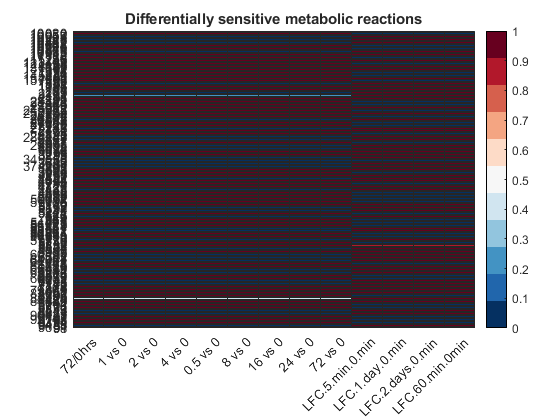

figure;
heatmap(final_data, ...
    'Colormap', redbluecmap);
ax = gca;
ax.XData = sample_ids;
ax.YData = gene_id;
title("Differentially sensitive metabolic reactions")

#### viii. Cluster differentially sensitive gene knockouts

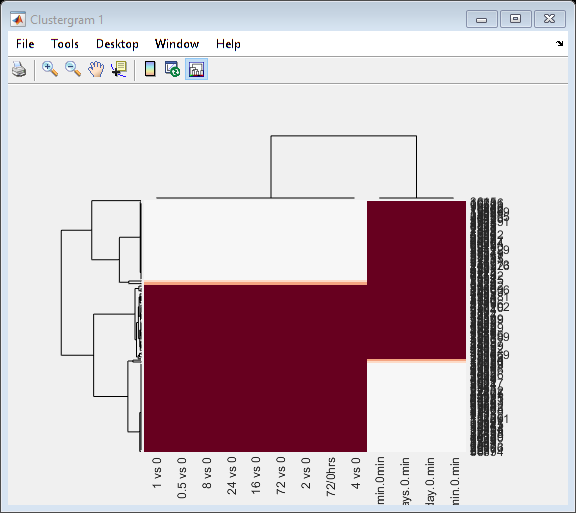

Clustergram object with 196 rows of nodes and 13 columns of nodes.



clustergram(final_data, ...
    'RowLabels', gene_id, ...
    'ColumnLabels', sample_ids, ...
    'Colormap', redbluecmap)